addpath('/Users/alec/Desktop/Documents/Professional/2024_OHern/many_body/composite_system/interparc');

% Request user to draw a closed, rounded shape
disp('Please draw a polygon.');

Please draw a polygon.


disp('Left-click to add points, right-click or press Enter to finish drawing.');

Left-click to add points, right-click or press Enter to finish drawing.


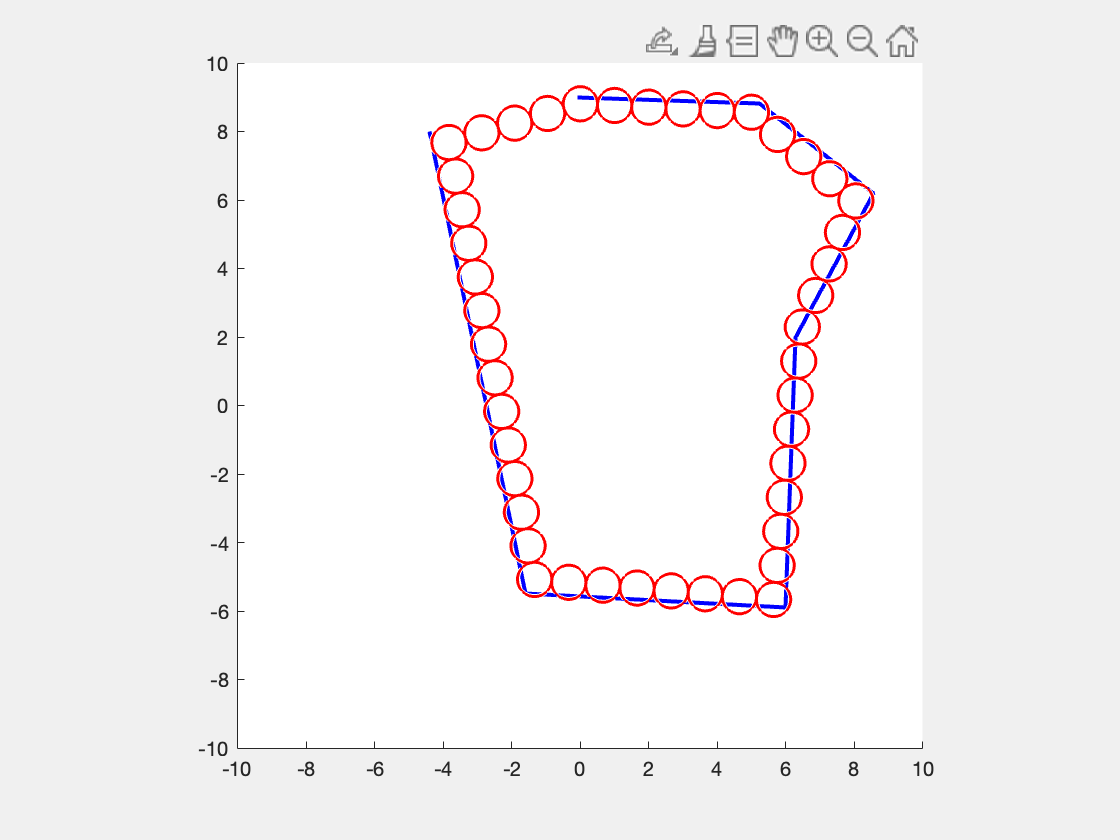

figure;
hold on;
axis equal;
xlim([-10 10]);
ylim([-10 10]);
sigma = 1;

x = [];
y = [];
while true
    [xi, yi, button] = ginput(1);
    if button == 1  % Left-click
        x = [x; xi];
        y = [y; yi];
        plot(x, y, 'b-', 'LineWidth', 2);
    else  % Right-click, Enter key, or any other button
        break;
    end
end

% Check if the shape is closed
is_closed = (x(end) == x(1) && y(end) == y(1));

[x_opt, y_opt] = optimize_vertices(x, y, sigma, is_closed);
particle_centers = generate_particle_centers(x_opt, y_opt, sigma, is_closed);

% Render the particles
render_particles(particle_centers, sigma);


% Display the number of particles used
num_particles = size(particle_centers, 1);
disp(['Number of particles used: ', num2str(num_particles)]);

Number of particles used: 45



function [x_opt, y_opt] = optimize_vertices(x, y, sigma, is_closed)
    num_vertices = length(x);
    
    % Define objective
    fun = @(coords) vertex_objective(coords, x, y);
    
    % Define constraint
    nonlcon = @(coords) vertex_constraints(coords, sigma, num_vertices, is_closed);
    
    % Set initial guess
    coords_init = [x; y];
    
    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off');
    
    % Perform constrained optimization
    coords_opt = fmincon(fun, coords_init, [], [], [], [], [], [], nonlcon, options);
    x_opt = coords_opt(1:num_vertices);
    y_opt = coords_opt(num_vertices+1:end);
end

function obj = vertex_objective(coords, x, y)
    num_vertices = length(x);
    x_adj = coords(1:num_vertices);
    y_adj = coords(num_vertices+1:end);
    
    % Calculate sum of squared distances between original and adjusted vertices
    obj = sum((x_adj - x).^2 + (y_adj - y).^2);
end

function [c, ceq] = vertex_constraints(coords, sigma, num_vertices, is_closed)
    x_adj = coords(1:num_vertices);
    y_adj = coords(num_vertices+1:end);
    
    if ~is_closed
        x_adj(end+1) = x_adj(1);
        y_adj(end+1) = y_adj(1);
    end
    
    edge_lengths = sqrt((x_adj(2:end) - x_adj(1:end-1)).^2 + (y_adj(2:end) - y_adj(1:end-1)).^2);
    
    % Inequality constraints (edge lengths >= sigma)
    c = sigma - edge_lengths;
    
    % Equality constraints (edge lengths == integer multiples of sigma)
    ceq = mod(edge_lengths, sigma);
end

function centers = generate_particle_centers(x, y, sigma, is_closed)
    num_vertices = length(x);
    centers = [x, y];
    
    for i = 1:num_vertices
        j = mod(i, num_vertices) + 1;
        edge_length = sqrt((x(j) - x(i))^2 + (y(j) - y(i))^2);
        num_particles_edge = round(edge_length / sigma) - 1;
        
        if num_particles_edge > 0
            t = linspace(0, 1, num_particles_edge+2);
            edge_coords = [linspace(x(i), x(j), num_particles_edge+2)', ...
                           linspace(y(i), y(j), num_particles_edge+2)'];
            centers = [centers; edge_coords(2:end-1, :)];
        end
    end
end

function render_particles(centers, sigma)
    viscircles(centers, sigma/2*ones(size(centers,1),1), 'Color', 'r', 'LineWidth', 1.5);
end